# Cấu trúc và thao tác dữ liệu

[Menu menu chính](matlab:open('MainMenu.mlx'))

Một máy tính lưu trữ từng bit dữ liệu dưới dạng số. Điều quan trọng là phải nhớ điều này để bạn có thể nhận ra những nơi bạn có thể cần phải rõ ràng về dạng dữ liệu bạn đang sử dụng. Tập lệnh này sẽ giải quyết một số loại dữ liệu chính mà bạn sẽ làm việc khi lập trình. Làm thế nào một máy tính có thể lưu trữ số vô tỷ $\pi$? Có con số nào mà con người làm việc dễ dàng với máy tính là khó khăn không? Tại sao hoặc tại sao không?

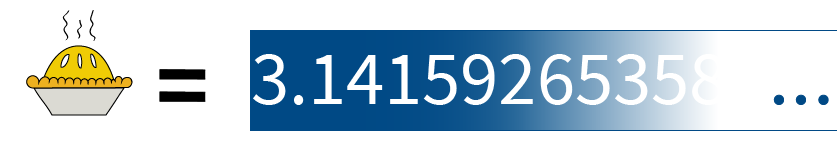

Kịch bản này sẽ bao gồm lập trình cơ bản với các số và văn bản.

**Trước khi bạn bắt đầu:**

Tập lệnh trực tiếp này được dự định sẽ được sử dụng với mã hiển thị và đầu ra nội tuyến. TRÊN **View** tab của công cụ MATLAB, trong **View** section, chọn **Output Inline**. Thay phiên, chọn **Output inline **Sử dụng biểu tượng Ở phía trên bên phải của Live Editor pane.

Tương tác với tập lệnh trực tiếp này sẽ xây dựng sự quen thuộc với MATLAB, vì các khái niệm và lệnh được giới thiệu cùng nhau, nhưng một số quen thuộc với môi trường biên tập trực tiếp đã được giới thiệu trong [Giới thiệu.MLX](matlab:open('./Introduction.mlx'))

Để có trải nghiệm tối ưu, hãy làm theo các hướng dẫn và các bước trong chuỗi đã cho. Chỉ tiến hành một phần mới sau khi hoàn thành phần trước, bao gồm cả chạy tất cả các khối mã.

## Cấu trúc dữ liệu đơn giản

Các loại dữ liệu đơn giản nhất là vô hướng: dữ liệu là một đơn vị thông tin như số hoặc cụm từ. Đầu tiên, hãy xem xét những gì xảy ra với các con số.

### Doubles

MỘT *double *là một [dấu phẩy động](https://www.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html) đại diện của một số.

   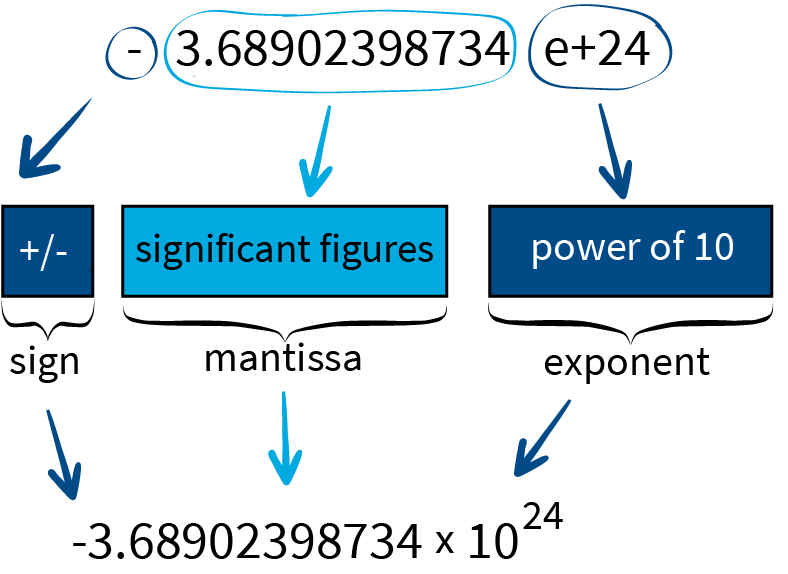

Số [dấu phẩy động](https://www.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html) sử dụng ký hiệu khoa học để cho phép phạm vi giá trị lớn nhất có thể có số chữ số cố định để làm việc. Tuy nhiên, việc xem xét cẩn thận sẽ lưu ý rằng có một số lượng hữu hạn các kết hợp có thể có của một số chữ số cố định và có vô số số thực có thể có trong cùng một phạm vi giá trị cho dù phạm vi nào được chọn để được thể hiện.

#### Số học dấu phẩy động

Hãy xem xét một chút toán học. Nếu như $a$ là một số hữu hạn, sau đó về mặt đại số bạn có thể thấy điều đó

$\frac{(1000a)}{1000} = 1000\left(\frac{a}{1000}\right) =$$\frac{1000a}{1000} = \left(\frac{1000}{1000}\right)a = a$.

Tuy nhiên, nếu chúng ta cho $a = 1\times 10^{-321}$ và tính toán điều này trên máy tính chúng tôi có:

1000*1e-321/1000
1e-321/1000*1000

[Nhớ](matlab:open('./CollectedProTips.mlx')), bạn có thể chạy khối mã này bằng cách nhấp vào   **Run Section** trong **Live Editor** tab.

Bạn có thể phản đối và nói rằng$1\times 10^{-321}$ là thực tế bằng $0$, vì vậy chúng ta hãy làm cho điều này cực đoan hơn một chút. Hãy nói rằng thay vì chỉ `1000 `bản sao của `1e-321 `bạn lấy `1e308 `bản sao. Sau đó bạn có thể nhân kết quả cuối cùng với `1e16`. Tương tự, trước tiên bạn có thể chia và sau đó nhân. Bạn nhận được gì bây giờ?

((1e308*1e-321)/1000)*1e16
((1e-321/1000)*1e308)*1e16

Về mặt toán học, các giá trị này phải giống hệt nhau, nhưng đó không phải là trường hợp cho các tính toán khi được thực hiện bởi máy tính vì các số mà máy tính có thể đại diện khác với các số mà con người có thể đại diện. Đơn giản hóa bằng tay, các giá trị của cả hai tính toán này là 1 khi tất cả các số là số thực. Sử dụng số dấu phẩy động, kết quả đầu tiên là gần 1, nhưng không chính xác là 1 và lần thứ hai xa hơn 1. Bạn có thể làm cho nó xa hơn so với kết quả số thực bằng cách sử dụng các bội số lớn hơn ở cuối tính toán.

#### Nhận ra những con số có thể gây ra vấn đề

Trên máy tính, chỉ có một số lượng hữu hạn các số có thể, vì vậy mỗi số thực được biểu thị bằng giá trị gần nhất trong tập hợp các số mà máy tính có thể lưu trữ. Điều này có nghĩa là các giá trị nhỏ khác không giảm xuống dưới ngưỡng khác với 0 và giá trị sẽ được làm tròn thành 0. Với một `double`, giá trị đó theo ở khoảng của `1e-324`. Khi máy tính đã làm tròn giá trị thành 0, bạn không có cơ hội khôi phục bằng cách di chuyển ra ngoài phạm vi đó vì bất kỳ số hữu hạn nào nhân với 0 sẽ trả về 0 và bất kỳ số 0 nào được thêm vào cũng sẽ trở lại 0.

**Chú ý đến độ lớn**

Điều này có nghĩa là bạn phải tránh làm việc với các giá trị đặc biệt lớn hoặc đặc biệt nhỏ bất cứ khi nào có thể. Nếu bạn đang làm việc với các số gần bằng không, bạn muốn nhân trước khi chia để cố gắng tránh vô tình làm tròn thành 0. Nếu bạn đang làm việc với số lượng rất lớn, bạn muốn chia trước khi nhân $\infty$. Khi thêm nhiều giá trị, điều quan trọng là bắt đầu từ các giá trị nhỏ nhất về độ lớn để tránh vô tình thêm 0 thông qua việc mất độ chính xác.

 **Bài tập 0.**

Hãy xem xét một máy tính chỉ tiết kiệm một con số quan trọng trong Mantissa, đó là 0-9 và cho phép một chữ số cho số mũ.

a. Kết quả của việc thêm vào `4+4+10`

b. Kết quả của việc thêm vào `10+4+4`

**Ví dụ bổ sung**

% 4/3 does not have an exact representation as a double
% The value of val should be 0, but it isn't
Val = 1-3*(4/3-1)

% In fact, 0.1 does not have an exact representation as a double. 
% With only a few terms the error doesn't build up too much
RawValHalf = 0.5;
SumValHalf = 0.1 + 0.1 + 0.1 + 0.1 + 0.1
RawValHalf - SumValHalf

% However, if we include a few more terms the error becomes apparent for
% some operations
RawValOne = 1;
SumValOne = 0.1 + 0.1 + 0.1 + 0.1 + 0.1 + 0.1 + 0.1 + 0.1 + 0.1 + 0.1
RawValOne-SumValOne

#### Giới hạn của độ chính xác

Hạn chế này có nghĩa là có sự mất độ chính xác vốn có khi thực hiện các tính toán kỹ thuật số.

Với tỷ lệ logarit của các số, độ chính xác này thay đổi khá nhiều. Lỗi nhỏ nhất là xung quanh `0`. Lệnh `eps(n) `sẽ cung cấp khoảng cách đến số dấu phẩy động lớn hơn tiếp theo. Về mặt toán học, đây sẽ là khoảng cách từ $n$ đến  $n+\epsilon$, do đó việc sử dụng `eps `cho epsilon.

eps(0)
eps(5)
eps(5^100)

 **Phản ánh**

- Chúng ta đã chọn các giá trị ví dụ như thế nào trong các dòng 1-4?

- Tại sao không có số `double ` giữa `5^100 `Và `5^100+1.5e544`

- Sử dụng `eps(n)`, bạn có thể nói khoảng bao nhiêu số `doubles `có ở đó giữa `1 `Và `2`? Giá trị của `N `Bạn có muốn kiểm tra không? Mức độ chính xác của giải pháp của bạn là gì?

**Bài tập 1**

Dung sai là một lượng biến thể cho phép giữa các giá trị sao cho chúng vẫn được coi là giống nhau. Một ví dụ phổ biến về dung sai quy định là trong sản xuất công nghiệp, chẳng hạn như tạo ra một vòng bi hoặc điện trở có kích thước tiêu chuẩn với điện trở nhất định. Nếu như `abs(x1-x2) < tolerance`, sau đó x`1 `Và `x2 `được coi là tương đương. Sản xuất các mặt hàng với dung sai nhỏ hơn thường sẽ đắt hơn. Với độ chính xác cho phép gấp đôi, số lượng chính xác hợp lý để mong đợi trong các trường hợp sau đây là gì?

a. Dung sai hợp lý cho các giá trị từ 1 đến 100 là gì?

b. Dung sai hợp lý cho các giá trị giữa 1e9 và 1e10 là gì?

% Bạn có thể sử dụng khối mã này để tính toán nếu bạn muốn.

### Strings

Điều quan trọng là có thể giao tiếp rõ ràng với những người khác cũng như với máy tính. Để làm như vậy, chúng ta cũng phải có thể sử dụng văn bản trong các chương trình máy tính cả dưới dạng dữ liệu và đầu ra. Máy tính mã hóa văn bản bằng số, giống như các bức ảnh. Mỗi ngôn ngữ lập trình có cú pháp riêng để tuyên bố rằng văn bản là một chuỗi. Xem xét những điều sau:

Num = 7.4
Str = "7.4"

Lệnh `class` sẽ trả về lớp (hoặc kiểu dữ liệu) của đối số. Trong trường hợp này, bạn có thể thấy rằng `num `là `double `Và `str `là một chuỗi.

class(Num)
class(Str)

#### Kết nối

Sau khi xác định chuỗi, bạn có thể muốn đặt chúng lại với nhau thành từ, cụm từ hoặc câu.

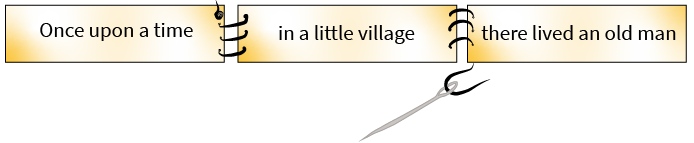

Hoạt động của các chuỗi tham gia được gọi là*Kết nối*. Trong Matlab, có thể kết hợp các chuỗi bằng cách sử dụngnhà điều hành.

Str1 = "gà tây rất dễ thương!"
Str2 = "Bạn có thích gà tây không?"
Str1 + str2

Điều này đã làm việc theo cách bạn mong đợi? Hãy nhớ rằng máy tính làm chính xác những gì bạn bảo họ làm. Ngoài việc là định hướng cực kỳ chi tiết về chính tả và viết hoa, bạn cần nhớ rằng không gian (đôi khi được gọi là Whitespace) cũng phải được biểu diễn bằng các số cho máy tính để theo dõi chúng. Để làm cho các chuỗi này kết hợp với nhau bình thường, bạn cần bao gồm không gian ở đâu đó như vậy:

Str1 + "" + str2

hoặc bằng cách bao gồm một không gian bổ sung trong một trong các chuỗi:

"Chúng tôi đã thấy" + num + "gà tây vào thứ năm!"

Bạn có thấy những gì đã xảy ra? Bạn có thể kết hợp một`sợi dây`với a`gấp đôi`Và kết quả là một chuỗi! Điều này có thể rất hữu ích để tạo ra đầu ra có thể đọc được của con người từ một chương trình. Mỗi ngôn ngữ lập trình có những ràng buộc riêng về cách các loại dữ liệu khác nhau có thể tương tác.

Để chia các chuỗi thành nhiều dòng văn bản, bạn cũng sẽ cần bao gồm "carriage return", từ thời của máy đánh chữ hoặc các ký tự "newline". Điều này có thể được thể hiện trong MATLAB với ký tự `newline`.

**Bài tập 2**

Concatenate các chuỗi được cung cấp và sử dụng thích hợp của `newline `Và`""`để tạo lại trò đùa sau trong một chuỗi có tên`câu nói đùa`Và một bình luận giải thích những gì bạn đang làm.

Knock Knock! 

Who's there?

Who! 

Who Who?

I didn't know you were an owl!

str1 = "Knock";
str2 = "Who";
str3 = "'s there";
str4 = "I didn't know you were an owl";
str5 = "!";
str6 = "?";

  **Pro-tip.**Ngoài việc chú ý đến khoảng trắng, điều quan trọng là phải phân định rõ ràng tổng số của một hướng dẫn. Trong trường hợp của chuỗi này, các hướng dẫn để tạo`câu nói đùa`Bằng cách kết hợp rất nhiều chuỗi có thể vượt xa giới hạn của một dòng văn bản tiêu chuẩn. Có hai cách tiêu chuẩn để tiếp cận vấn đề. Đầu tiên là chia một hướng dẫn dài thành kết hợp các hướng dẫn ngắn hơn như

% Excerpt from "The Land of Beyond", by Robert William Service (1874-1958)

Poem =     "Have ever you heard of the Land of Beyond,
     That dreams at the gates of the day?"


Poem = "Have ever you heard of the Land of Beyond,"; 
Poem = Poem + newline + "That dreams at the gates";
Poem = Poem + " of the day?"

Poem =     "Have ever you heard of the Land of Beyond,
     That dreams at the gates of the day?
     Alluring it lies at the skirts of the skies,
     And ever so far away"


Thay phiên, bạn có thể hướng dẫn máy tính rằng nhiều dòng mã nên được coi là một dòng logic duy nhất cho các mục đích giải thích ý nghĩa, chẳng hạn như

Poem = Poem + newline + "Alluring it lies at the" + ...

a = Inf

    " skirts of the skies," + newline + "And ever " + ...

b = Inf

    "so far away"

c = NaN

  **Thử**. Điều gì xảy ra nếu bạn xóa các hình elip (...) khỏi khối mã ở trên? Tại sao? Bạn có thể sử dụng phá vỡ dòng trong giải pháp của bạn để Bài tập 2 Để làm cho mã dễ đọc hơn?

### Ký tự đặc biệt

Ngôn ngữ lập trình cũng có nhu cầu đại diện cho các ý tưởng không phù hợp như cụm từ hoặc số. Chạy mã trong phần này và xem xét kết quả:

a = 2^1024

d = NaN

b = 10^400

dAlt = 0

c = 2^1024-10^400
d = 0*2^1024
dAlt = (0*2^1020)*2^4

 **Phản ánh**

- Bạn có đồng ý với những câu trả lời này không? Làm thế nào bạn sẽ thể hiện giá trị của`d`

- Tại sao bạn nghĩ `dAlt `đánh giá một giá trị khác với `d`

- Nếu bạn chấp nhận đề xuất rằng `a = `$\infty$ Và `b = `$\infty$, làm thế nào bạn sẽ thể hiện các giá trị của `c `Và `d`

#### `Inf`

`Inf `là biểu tượng đại diện cho khái niệm vô cực trong Matlab. Đây có thể là giá trị là giới hạn của chuỗi


$$1,2,3,4,5,6,7,8,9,10,\ldots$$


hoặc nó có thể là giá trị của

$\lim_{x \to 0} \frac{1}{x^2}$.

Theo cùng một cách$\ Infty$đại diện cho các số lớn hơn bất cứ thứ gì chúng ta có thể đếm,`Inf`Đại diện cho bất kỳ số nào lớn hơn số lớn nhất mà máy tính có thể đại diện. Trong trường hợp này, đó là

realmax

ans = 1.7977e+308

Vì `Inf `được mô tả bởi một bất đẳng thức chứ không phải là một giá trị chính xác, nó không hoạt động giống như các số trong các tính toán số học.

#### `NaN`

`NaN `là một biểu tượng là viết tắt của "Not a Number". Trong các lớp toán, bạn có thể đã gặp phải khái niệm "các hình thức không xác định", chẳng hạn như$\frac{0}{0}$ or $\frac{\infty}{\infty}$ or $0\cdot\infty$. `NaN `là ngôn ngữ lập trình tương đương được sử dụng để thể hiện bất kỳ giá trị nào trong môi trường số không phải là một số.

**Bài tập 3**

Giá trị số nguyên nhỏ nhất của `k `làm cho `2^k `trở thành` Inf `Trong Matlab? Bạn có thể giải quyết điều này mà không đoán và kiểm tra?

% Sử dụng khối mã này để tính toán liên quan đến bài tập 3

## Tiếp tục

Bạn có thể tìm hiểu thêm về các lớp số và văn bản bằng cách đọc tài liệu.

[Các loại số](https://www.mathworks.com/help/matlab/numeric-types.html)

[Các loại văn bản](https://www.mathworks.com/help/matlab/characters-and-strings.html)

Có nhiều loại dữ liệu có thể, nhưng điều quan trọng là có thể thêm một chút cấu trúc vào dữ liệu bạn sẽ yêu cầu một máy tính thao tác. Một cấu trúc tiêu chuẩn khá hữu ích được thảo luận trong [Mảng.mlx](matlab:open('./Arrays.mlx'))

[Menu menu chính](matlab:open('MainMenu.mlx'))